rand('seed', 314);

x = rand(40, 1);
y = rand(40, 1);
class = (2 * x < y + 0.5) + 1;

A1 = [x(class == 1), y(class == 1)];
A2 = [x(class == 2), y(class == 2)];

Xi = [A1; A2];

yi = [ones(size(A1, 1), 1); -ones(size(A2, 1), 1)];

cvx_begin
    variables v(2) a
    minimise(norm(v))
    subject to
        (yi .* (Xi * v + a)) >= 1

cvx_end

 
Calling SDPT3 4.0: 43 variables, 4 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  4
 dim. of socp   var  =  3,   num. of socp blk  =  1
 dim. of linear var  = 40
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.2e+01|9.5e+00|5.1e+03|-5.059644e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.035|0.816|5.0e+01|1.8e+00|5.1e+03|-5.038279e+02 -3.479029e+02| 0:0:00| chol  1  1 
 2|0.827|1.000|8.6e+00|8.7e-03|9.1e+02|-2.150149e+02 -1.173826e+02| 0:0:00| chol  1  1 
 3|1.000|0.985|1.1e-05|9.9e-04|3.0e+01


fprintf('v = [ ');

v = [ 

fprintf('%2.6f ', v);

43.959605 -19.441270 

fprintf('] a = %2.6f \n', a);

] a = -12.416990 


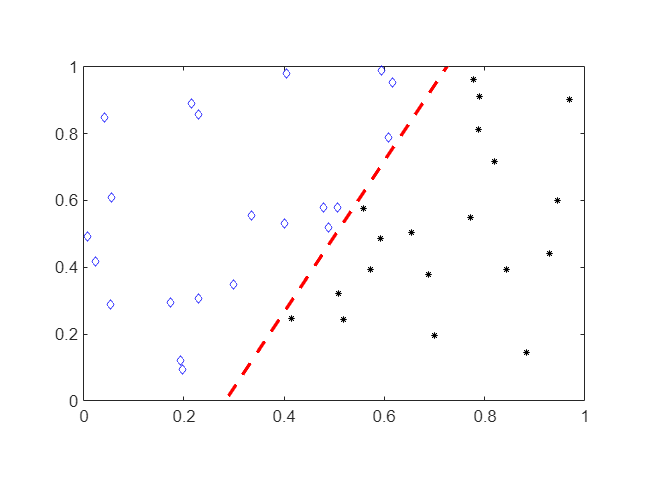


x_line = [min(Xi(:, 1)), max(Xi(:, 1))];
y_line = -(a +v(1) * x_line) / v(2);
plot(x_line, y_line, 'r--', 'LineWidth', 2);

hold on9
plot(A1(:, 1), A1(:, 2), '*', 'MarkerSize', 4, 'Color', 'black');
plot(A2(:, 1), A2(:, 2), 'd', 'MarkerSize', 4, 'Color', 'blue');
hold off

axis([0 1 0 1]);

daspect([1 1.5 1]);